# 美赛培训第二次课：MATLAB入门与数据处理基础

## 授课人：Mr.Guo

## 1. 课程回顾与目标

% 上节课内容：数据类型、描述性统计量、SPSS基础
% 本节课目标：掌握MATLAB环境与基本操作，能够独立完成数据处理流程

## 2. MATLAB环境介绍

 2.1 启动MATLAB

 桌面布局：命令窗口、工作区、当前文件夹、编辑器

% 2.2 首次运行演示
disp('欢迎来到MATLAB美赛培训！')

欢迎来到MATLAB美赛培训！


disp('今天我们将学习：')

今天我们将学习：


disp('1. MATLAB基础语法')

1. MATLAB基础语法


disp('2. 数据导入与清洗')

2. 数据导入与清洗


disp('3. 统计量计算')

3. 统计量计算


disp('4. 数据可视化')

4. 数据可视化


## 3. MATLAB基础语法

 3.1 变量与赋值

% 清除工作区
clear
clc

% 标量赋值
a = 10;
b = 3.14;
c = 'Hello MATLAB';

% 显示变量
disp('标量示例：')

标量示例：


disp(['a = ', num2str(a)])

a = 10


disp(['b = ', num2str(b)])

b = 3.14


disp(['c = ', c])

c = Hello MATLAB



% 3.2 向量和矩阵
% 行向量
row_vec = [1, 2, 3, 4, 5];

% 列向量
col_vec = [1; 2; 3; 4; 5];

% 矩阵
matrix = [1, 2, 3; 4, 5, 6; 7, 8, 9];

disp(' ')

disp('向量和矩阵示例：')

向量和矩阵示例：


disp('行向量：')

行向量：


disp(row_vec)

     1     2     3     4     5



disp('列向量：')

列向量：


disp(col_vec)

     1
     2
     3
     4
     5



disp('3x3矩阵：')

3x3矩阵：


disp(matrix)

     1     2     3
     4     5     6
     7     8     9




% 3.3 常用矩阵操作
% 生成特殊矩阵
zeros_mat = zeros(3, 3);  % 全零矩阵
ones_mat = ones(2, 4);    % 全一矩阵
eye_mat = eye(3);         % 单位矩阵
rand_mat = rand(3, 3);    % 随机矩阵（0-1之间）

disp(' ')

disp('特殊矩阵示例：')

特殊矩阵示例：


disp('3x3零矩阵：')

3x3零矩阵：


disp(zeros_mat)

     0     0     0
     0     0     0
     0     0     0



disp('3x3单位矩阵：')

3x3单位矩阵：


disp(eye_mat)

     1     0     0
     0     1     0
     0     0     1



disp('3x3随机矩阵：')

3x3随机矩阵：


disp(rand_mat)

    0.1869    0.6463    0.2760
    0.4898    0.7094    0.6797
    0.4456    0.7547    0.6551



## 4. 数据导入与处理

4.1 创建示例数据（模拟糖尿病数据集）

% 在实际比赛中，你会从文件导入数据，这里我们先创建示例数据

num_patients = 100;

% 创建表格
patient_id = (1:num_patients)';
gender = randi([0, 1], num_patients, 1);  % 0-女性，1-男性
age = randi([20, 80], num_patients, 1);
glucose = 70 + 30*randn(num_patients, 1);  % 血糖值
blood_pressure = 80 + 20*randn(num_patients, 1);  % 血压
bmi = 25 + 5*randn(num_patients, 1);  % 身体质量指数

% 创建表格
diabetes_data = table(patient_id, gender, age, glucose, blood_pressure, bmi, ...
    'VariableNames', {'ID', 'Gender', 'Age', 'Glucose', 'BP', 'BMI'});

% 添加一些缺失值（模拟真实数据）
missing_indices = randi([1, num_patients], 10, 1);
diabetes_data.Glucose(missing_indices(1:5)) = NaN;
diabetes_data.BP(missing_indices(6:10)) = NaN;

disp(' ')

disp('创建的示例糖尿病数据（前10行）：')

创建的示例糖尿病数据（前10行）：


disp(diabetes_data(1:10, :))

    ID    Gender    Age    Glucose      BP       BMI  
    __    ______    ___    _______    ______    ______

     1      0       77     47.975     97.619    24.686
     2      0       49     69.076     86.464     14.89
     3      0       49      76.97     64.317    20.089
     4      1       40     82.792     43.893    28.063
     5      0       74     58.816     117.17    24.726
     6      1       42     62.906     67.909    19.406
     7      0       26     130.71     82.067    21.868
     8      1       67     2.2494     91.263    26.248
     9      0       43     136.88     82.272    20.035
    10      1       34     80.127     61.905    29.875




% 4.2 数据导入（从文件）
% 在实际使用中，你可以从CSV、Excel等文件导入数据
% 以下代码演示如何从CSV文件导入（需要实际文件存在）

% 将示例数据保存为CSV文件，以便演示导入过程
writetable(diabetes_data, 'diabetes_sample.csv');

% 现在从CSV文件导入数据
imported_data = readtable('diabetes_sample.csv');

disp(' ')

disp('从CSV文件导入的数据（前5行）：')

从CSV文件导入的数据（前5行）：


disp(imported_data(1:5, :))

    ID    Gender    Age    Glucose      BP       BMI  
    __    ______    ___    _______    ______    ______

    1       0       77     47.975     97.619    24.686
    2       0       49     69.076     86.464     14.89
    3       0       49      76.97     64.317    20.089
    4       1       40     82.792     43.893    28.063
    5       0       74     58.816     117.17    24.726




% 4.3 数据清洗
disp(' ')

disp('=== 数据清洗 ===')

=== 数据清洗 ===



% 检查缺失值
missing_glucose = sum(isnan(imported_data.Glucose));
missing_bp = sum(isnan(imported_data.BP));

disp(['血糖缺失值数量: ', num2str(missing_glucose)])

血糖缺失值数量: 5


disp(['血压缺失值数量: ', num2str(missing_bp)])

血压缺失值数量: 4



% 方法1：删除包含缺失值的行
clean_data1 = imported_data;
clean_data1(any(ismissing(clean_data1), 2), :) = [];

disp(' ')

disp('方法1：删除缺失值后的数据行数：')

方法1：删除缺失值后的数据行数：


disp(['原始行数: ', num2str(height(imported_data))])

原始行数: 100


disp(['清洗后行数: ', num2str(height(clean_data1))])

清洗后行数: 91



% 方法2：用平均值填充缺失值
clean_data2 = imported_data;

% 计算血糖和血压的平均值（忽略NaN）
mean_glucose = nanmean(clean_data2.Glucose);
mean_bp = nanmean(clean_data2.BP);

% 填充缺失值
clean_data2.Glucose(isnan(clean_data2.Glucose)) = mean_glucose;
clean_data2.BP(isnan(clean_data2.BP)) = mean_bp;

disp(' ')

disp('方法2：用平均值填充缺失值')

方法2：用平均值填充缺失值


disp(['血糖平均值（用于填充）: ', num2str(mean_glucose)])

血糖平均值（用于填充）: 67.454


disp(['血压平均值（用于填充）: ', num2str(mean_bp)])

血压平均值（用于填充）: 79.431



% 4.4 数据筛选
disp(' ')

disp('=== 数据筛选 ===')

=== 数据筛选 ===



% 筛选年龄大于50的患者
elderly_patients = clean_data2(clean_data2.Age > 50, :);

disp('年龄大于50岁的患者（前5行）：')

年龄大于50岁的患者（前5行）：


disp(elderly_patients(1:min(5, height(elderly_patients)), :))

    ID    Gender    Age    Glucose      BP       BMI  
    __    ______    ___    _______    ______    ______

     1      0       77     47.975     97.619    24.686
     5      0       74     58.816     117.17    24.726
     8      1       67     2.2494     91.263    26.248
    14      1       77     61.658     62.784    25.996
    15      0       78     82.681     95.693    17.395




% 筛选高血糖患者（血糖>100）
high_glucose_patients = clean_data2(clean_data2.Glucose > 100, :);

disp(' ')

disp('血糖大于100的患者（前5行）：')

血糖大于100的患者（前5行）：


disp(high_glucose_patients(1:min(5, height(high_glucose_patients)), :))

    ID    Gender    Age    Glucose      BP       BMI  
    __    ______    ___    _______    ______    ______

     7      0       26     130.71     82.067    21.868
     9      0       43     136.88     82.272    20.035
    11      1       44        100     70.646    21.796
    22      1       22     102.48     83.844    29.077
    23      0       30     100.18     63.554    28.994



## 5. 基本统计量计算


% 5.1 集中趋势度量
disp(' ')

disp('=== 集中趋势度量 ===')

=== 集中趋势度量 ===



% 年龄的统计量
age_data = clean_data2.Age;

mean_age = mean(age_data);
median_age = median(age_data);
mode_age = mode(age_data);

disp(['年龄 - 均值: ', num2str(mean_age)])

年龄 - 均值: 48.79


disp(['年龄 - 中位数: ', num2str(median_age)])

年龄 - 中位数: 47


disp(['年龄 - 众数: ', num2str(mode_age)])

年龄 - 众数: 38



% 5.2 离散趋势度量
disp(' ')

disp('=== 离散趋势度量 ===')

=== 离散趋势度量 ===



std_age = std(age_data);
var_age = var(age_data);
range_age = range(age_data);
iqr_age = iqr(age_data);  % 四分位距

disp(['年龄 - 标准差: ', num2str(std_age)])

年龄 - 标准差: 16.4239


disp(['年龄 - 方差: ', num2str(var_age)])

年龄 - 方差: 269.7433


disp(['年龄 - 极差: ', num2str(range_age)])

年龄 - 极差: 59


disp(['年龄 - 四分位距: ', num2str(iqr_age)])

年龄 - 四分位距: 27.5



% 5.3 分位数
disp(' ')

disp('=== 分位数 ===')

=== 分位数 ===



percentiles = prctile(age_data, [25, 50, 75, 90, 95]);
disp(['年龄 - 25百分位数: ', num2str(percentiles(1))])

年龄 - 25百分位数: 34.5


disp(['年龄 - 50百分位数（中位数）: ', num2str(percentiles(2))])

年龄 - 50百分位数（中位数）: 47


disp(['年龄 - 75百分位数: ', num2str(percentiles(3))])

年龄 - 75百分位数: 62


disp(['年龄 - 90百分位数: ', num2str(percentiles(4))])

年龄 - 90百分位数: 74.5


disp(['年龄 - 95百分位数: ', num2str(percentiles(5))])

年龄 - 95百分位数: 77



% 5.4 分布形态度量
disp(' ')

disp('=== 分布形态度量 ===')

=== 分布形态度量 ===



% 偏度（Skewness）
skew_age = skewness(age_data);

% 峰度（Kurtosis）
kurt_age = kurtosis(age_data);

disp(['年龄 - 偏度: ', num2str(skew_age)])

年龄 - 偏度: 0.21832


if skew_age > 0
    disp('  分布右偏（正偏）')
elseif skew_age < 0
    disp('  分布左偏（负偏）')
else
    disp('  分布对称')
end

  分布右偏（正偏）



disp(['年龄 - 峰度: ', num2str(kurt_age)])

年龄 - 峰度: 1.9974


if kurt_age > 3
    disp('  分布比正态分布更陡峭（尖峰）')
elseif kurt_age < 3
    disp('  分布比正态分布更平缓（平峰）')
else
    disp('  与正态分布峰度相同')
end

  分布比正态分布更平缓（平峰）



% 5.5 分组统计
disp(' ')

disp('=== 分组统计（按性别） ===')

=== 分组统计（按性别） ===



% 按性别分组
male_data = clean_data2(clean_data2.Gender == 1, :);
female_data = clean_data2(clean_data2.Gender == 0, :);

% 计算各组的统计量
male_stats = [mean(male_data.Age), std(male_data.Age), ...
              mean(male_data.Glucose), std(male_data.Glucose)];
female_stats = [mean(female_data.Age), std(female_data.Age), ...
                mean(female_data.Glucose), std(female_data.Glucose)];

% 创建结果表格
var_names = {'平均年龄', '年龄标准差', '平均血糖', '血糖标准差'};
row_names = {'男性', '女性'};
group_stats = array2table([male_stats; female_stats], ...
    'VariableNames', var_names, 'RowNames', row_names);

disp(group_stats)

            平均年龄    年龄标准差    平均血糖    血糖标准差
            _______    _________    _______    _________

    男性    45.957      16.277      62.378      30.635  
    女性    51.204       16.31      71.778      28.435  



## 6. 数据可视化

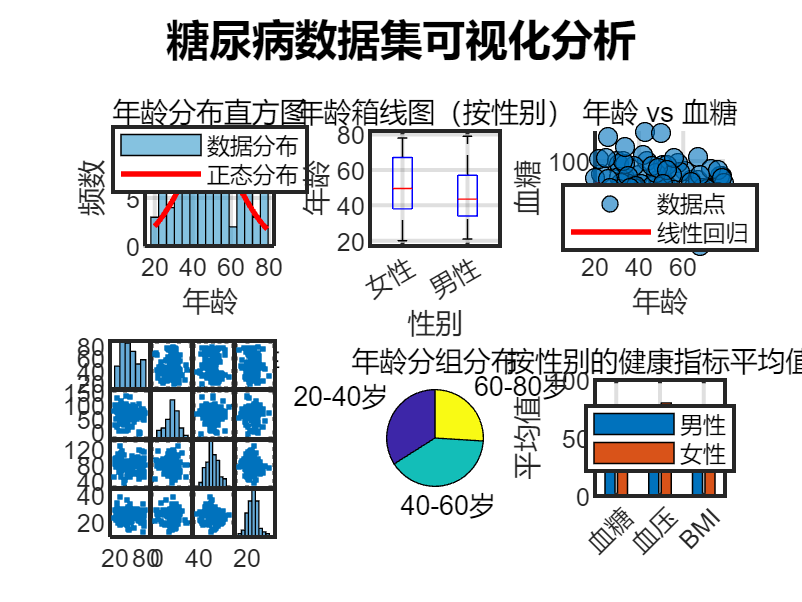


% 6.1 设置图形参数
set(groot, 'DefaultFigureColor', 'white')
set(groot, 'DefaultAxesFontSize', 12)
set(groot, 'DefaultAxesLineWidth', 1.5)

% 6.2 直方图 - 年龄分布
figure('Position', [100, 100, 800, 600])

subplot(2, 3, 1)
histogram(clean_data2.Age, 15, 'FaceColor', [0.2, 0.6, 0.8], 'EdgeColor', 'black')
xlabel('年龄')
ylabel('频数')
title('年龄分布直方图')
grid on

% 添加正态分布曲线
hold on
x = linspace(min(clean_data2.Age), max(clean_data2.Age), 100);
pdf = normpdf(x, mean(clean_data2.Age), std(clean_data2.Age));
plot(x, pdf * numel(clean_data2.Age) * (max(clean_data2.Age)-min(clean_data2.Age))/15, ...
    'r-', 'LineWidth', 2)
legend('数据分布', '正态分布', 'Location', 'best')
hold off

% 6.3 箱线图 - 按性别分组
subplot(2, 3, 2)
boxplot(clean_data2.Age, clean_data2.Gender, 'Labels', {'女性', '男性'})
xlabel('性别')
ylabel('年龄')
title('年龄箱线图（按性别）')
grid on

% 6.4 散点图 - 年龄 vs 血糖
subplot(2, 3, 3)
scatter(clean_data2.Age, clean_data2.Glucose, 50, ...
    'filled', 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'black')
xlabel('年龄')
ylabel('血糖')
title('年龄 vs 血糖')
grid on

% 添加回归线
hold on
p = polyfit(clean_data2.Age, clean_data2.Glucose, 1);
yfit = polyval(p, clean_data2.Age);
plot(clean_data2.Age, yfit, 'r-', 'LineWidth', 2)
legend('数据点', '线性回归', 'Location', 'best')
hold off

% 6.5 散点图矩阵
subplot(2, 3, 4)
plotmatrix([clean_data2.Age, clean_data2.Glucose, clean_data2.BP, clean_data2.BMI])
title('散点图矩阵')

% 6.6 饼图 - 年龄分组
subplot(2, 3, 5)
age_groups = discretize(clean_data2.Age, [20, 40, 60, 80]);
age_group_counts = histcounts(age_groups, 1:4);
labels = {'20-40岁', '40-60岁', '60-80岁'};
pie(age_group_counts, labels)
title('年龄分组分布')

% 6.7 条形图 - 按性别的平均统计量
subplot(2, 3, 6)
male_values = [mean(male_data.Glucose), mean(male_data.BP), mean(male_data.BMI)];
female_values = [mean(female_data.Glucose), mean(female_data.BP), mean(female_data.BMI)];

bar_data = [male_values; female_values]';
bar(bar_data)
set(gca, 'XTickLabel', {'血糖', '血压', 'BMI'})
ylabel('平均值')
legend({'男性', '女性'}, 'Location', 'best')
title('按性别的健康指标平均值')
grid on

sgtitle('糖尿病数据集可视化分析', 'FontSize', 16, 'FontWeight', 'bold')

## 7. 综合练习


% 7.1 练习题目
disp(' ')
disp('=== 综合练习 ===')
disp('请完成以下任务：')
disp('1. 计算所有数值变量的描述性统计量（均值、标准差、最小值、最大值）')
disp('2. 创建年龄和BMI的二维直方图')
disp('3. 计算并显示相关性矩阵')
disp('4. 保存清洗后的数据到新文件')

% 7.2 参考答案
disp(' ')
disp('=== 参考答案 ===')

% 任务1：计算所有数值变量的描述性统计量
disp('任务1：描述性统计量')
numeric_vars = clean_data2(:, {'Age', 'Glucose', 'BP', 'BMI'});
stats_table = varfun(@(x) [mean(x), std(x), min(x), max(x)], numeric_vars);
stats_table.Properties.VariableNames = {'Age_stats', 'Glucose_stats', 'BP_stats', 'BMI_stats'};
stats_array = table2array(stats_table);

% 创建更易读的表格
stat_names = {'均值', '标准差', '最小值', '最大值'};
var_names = {'年龄', '血糖', '血压', 'BMI'};
final_stats = array2table(stats_array', 'VariableNames', var_names, 'RowNames', stat_names);
disp(final_stats)

% 任务2：创建年龄和BMI的二维直方图
figure('Position', [200, 200, 800, 400])

subplot(1, 2, 1)
histogram2(clean_data2.Age, clean_data2.BMI, 20, ...
    'FaceColor', 'flat', 'DisplayStyle', 'tile')
xlabel('年龄')
ylabel('BMI')
title('年龄-BMI二维直方图')
colorbar
grid on

% 任务3：计算并显示相关性矩阵
subplot(1, 2, 2)
corr_matrix = corrcoef(table2array(numeric_vars), 'Rows', 'complete');
imagesc(corr_matrix)
colorbar
title('变量间相关性矩阵')
xticks(1:4)
yticks(1:4)
xticklabels(var_names)
yticklabels(var_names)

% 添加相关系数值
for i = 1:4
    for j = 1:4
        text(j, i, sprintf('%.2f', corr_matrix(i, j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'white', 'FontWeight', 'bold')
    end
end

sgtitle('综合练习结果', 'FontSize', 14, 'FontWeight', 'bold')

% 任务4：保存清洗后的数据到新文件
writetable(clean_data2, 'cleaned_diabetes_data.xlsx');
disp(' ')
disp('任务4：清洗后的数据已保存为 "cleaned_diabetes_data.xlsx"')


## 8. 扩展内容：高级统计与假设检验


% 8.1 t检验示例：比较男女患者的血糖水平
disp(' ')

disp('=== 高级统计：假设检验 ===')

=== 高级统计：假设检验 ===


disp('t检验：比较男女患者的血糖水平是否有显著差异')

t检验：比较男女患者的血糖水平是否有显著差异



[h, p, ci, stats] = ttest2(male_data.Glucose, female_data.Glucose);

disp(['检验结果：h = ', num2str(h), ', p = ', num2str(p)])

检验结果：h = 0, p = 0.11504


disp(['置信区间：[', num2str(ci(1)), ', ', num2str(ci(2)), ']'])

置信区间：[-21.133, 2.3317]


disp(['t统计量：', num2str(stats.tstat)])

t统计量：-1.5901


disp(['自由度：', num2str(stats.df)])

自由度：98



if h == 1
    disp('结论：拒绝原假设，男女血糖水平有显著差异')
else
    disp('结论：不能拒绝原假设，男女血糖水平无显著差异')
end

结论：不能拒绝原假设，男女血糖水平无显著差异



% 8.2 线性回归示例
disp(' ')

disp('线性回归：用年龄预测血糖水平')

线性回归：用年龄预测血糖水平



% 准备数据
X = [ones(size(clean_data2.Age)), clean_data2.Age];
y = clean_data2.Glucose;

% 线性回归
[b, bint, r, rint, stats] = regress(y, X);

disp(['回归方程：血糖 = ', num2str(b(1)), ' + ', num2str(b(2)), ' × 年龄'])

回归方程：血糖 = 71.7693 + -0.088447 × 年龄


disp(['R平方：', num2str(stats(1))])

R平方：0.0023935


disp(['F统计量：', num2str(stats(2))])

F统计量：0.23512


disp(['p值：', num2str(stats(3))])

p值：0.62883


## 9. 课程总结与作业


% 9.1 本节课重点回顾
disp(' ')

disp('=== 课程总结 ===')

=== 课程总结 ===


disp('本节课学习了：')

本节课学习了：


disp('1. MATLAB基础语法与操作')

1. MATLAB基础语法与操作


disp('2. 数据导入、清洗与预处理')

2. 数据导入、清洗与预处理


disp('3. 描述性统计量计算')

3. 描述性统计量计算


disp('4. 数据可视化（直方图、箱线图、散点图等）')

4. 数据可视化（直方图、箱线图、散点图等）


disp('5. 分组统计与假设检验')

5. 分组统计与假设检验


disp('6. MATLAB实用技巧（向量化、匿名函数等）')

6. MATLAB实用技巧（向量化、匿名函数等）



% 9.2 课后作业
disp(' ')

disp('=== 课后作业 ===')

=== 课后作业 ===


disp('请完成以下任务：')

请完成以下任务：


disp('1. 使用MATLAB自带数据集 "patients.mat"（load patients.mat）')

1. 使用MATLAB自带数据集 "patients.mat"（load patients.mat）


disp('2. 计算身高、体重、收缩压、舒张压的描述性统计量')

2. 计算身高、体重、收缩压、舒张压的描述性统计量


disp('3. 按性别分组，比较各指标差异')

3. 按性别分组，比较各指标差异


disp('4. 绘制至少3种不同类型的可视化图表')

4. 绘制至少3种不同类型的可视化图表


disp('5. 尝试进行简单的预测分析（如用年龄预测血压）')

5. 尝试进行简单的预测分析（如用年龄预测血压）


% 加载示例数据供作业参考
disp(' ')

disp('作业参考：加载patients数据集')

作业参考：加载patients数据集


try
    load patients.mat
    disp('patients数据集加载成功！')
    disp('可用变量：')
    whos
catch
    disp('未找到patients数据集，请确保MATLAB版本支持')
end

patients数据集加载成功！


可用变量：


  Name                            Size            Bytes  Class      Attributes

  Age                           100x1               800  double               
  Diastolic                     100x1               800  double               
  Gender                        100x1             11412  cell                 
  Height                        100x1               800  double               
  LastName                      100x1             11616  cell                 
  Location                      100x1             14208  cell                 
  SelfAssessedHealthStatus      100x1             11540  cell                 
  Smoker                        100x1               100  logical              
  Systolic                      100x1               800  double               
  Weight                        100x1               800  double               





disp(' ')

disp('=== 课程结束 ===')

=== 课程结束 ===


disp('谢谢参与！如有问题，请随时联系Mr.Guo')

谢谢参与！如有问题，请随时联系Mr.Guo
